syms lambda c f dt u1 u2
A = [0 1;-lambda,-c]

$$A = \left(\begin{array}{cc} 0 & 1\\ -\lambda & -c \end{array}\right)$$

U = [u1;u2]

$$U = \left(\begin{array}{c} u_{1}\\ u_{2} \end{array}\right)$$

F = [0;f]

$$F = \left(\begin{array}{c} 0\\ f \end{array}\right)$$

fc = (eye(2) - A*dt)\(F*dt + U)

$$fc = \left(\begin{array}{c} \frac{{\mathrm{dt}}^{2}\,f+\mathrm{dt}\,u_{2}+u_{1}+c\,\mathrm{dt}\,u_{1}}{1+{\mathrm{dt}}^{2}\,\lambda +c\,\mathrm{dt}}\\ \frac{\mathrm{dt}\,f+u_{2}-\mathrm{dt}\,\lambda \,u_{1}}{1+{\mathrm{dt}}^{2}\,\lambda +c\,\mathrm{dt}} \end{array}\right)$$

fm = matlabFunction(symfun(fc,[u1,u2,lambda,c,f,dt]))

fm = 包含以下值的 function_handle :
    @(u1,u2,lambda,c,f,dt)[(u1+dt.*u2+dt.^2.*f+c.*dt.*u1)./(c.*dt+dt.^2.*lambda+1.0);(u2+dt.*f-dt.*lambda.*u1)./(c.*dt+dt.^2.*lambda+1.0)]


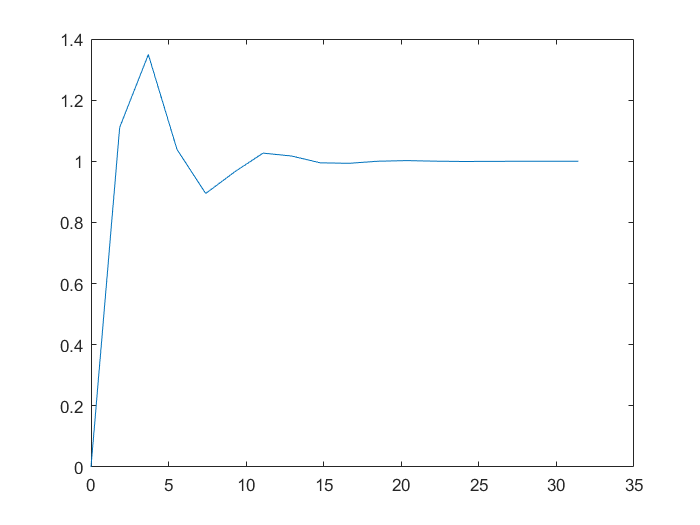


ts = linspace(0,10*pi,18);
dts = ts(2)-ts(1);
us = nan(size(ts)); dus = nan(size(ts));
us(1) = 0; dus(1) = 0;
K = 1;
for it = 2:numel(us)
    un = fm(us(it-1),dus(it-1), K, -dts/sqrt(K) * pi * 0.125, 1, dts);
    us(it) = un(1); dus(it) = un(2);
end
plot(ts,us)